# Rotations

More on representation of orientation

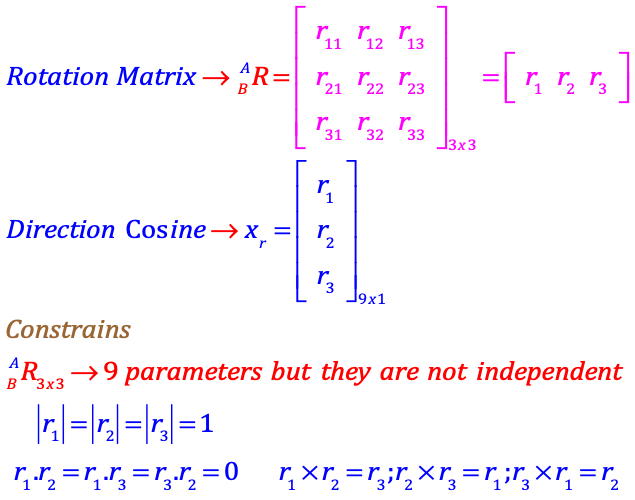

## Rotation matrix 

Let's check that Rotational Matrix is orthogonal

B=rotz(pi/5)*roty(pi/4)*rotx(pi/3) % RTB functions

Any column or row are unitary vector. i.e. has norm =1


$$\left| {\hat X} \right| = 1;\left| {\hat Y} \right| = 1 ;\left| {\hat Z} \right| = 1$$


unitary=norm(B(:,2))
unitary=norm(B(1,:))

The projection of any unitary vector yiels 0


$$\hat X \cdot \hat Y = \hat X \cdot \hat Y = \hat X \cdot \hat Z = 0;\]$$


projection=dot(B(:,1),B(:,2))
projection=B(:,2)'*B(:,1)

## Three angle representation

Rotation Matrix has 9 parameters but six dependences = 3 

It can be specified by just three parameters,$\left(\alpha \beta \gamma \right)$


$$\left\{ A \right\} \to {}_B^A{R_{(\alpha \beta \gamma )}} \to \left\{ B \right\}$$


Play with 

tripleangle

### Postmultiplication / Premultiplication

syms alpha beta gamma real
R_zyx=rotz(alpha)*roty(beta)*rotx(gamma)

See code at: Rotation_Fixed_moving_frames_2.mlx

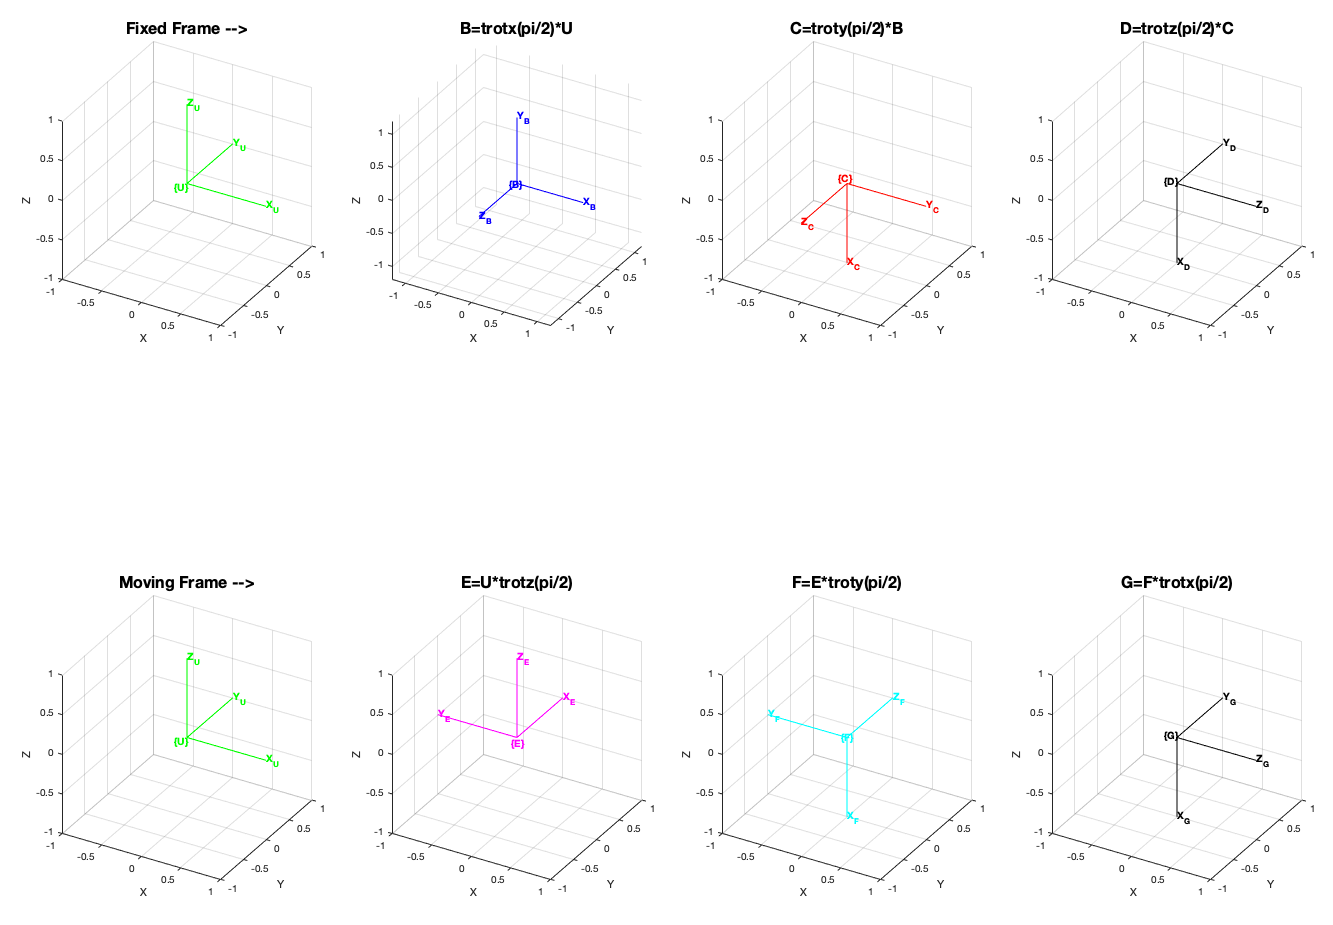

## Orientation of the End effector

### Decoupled. Puma 6R

Play with the options of SE3.teach

Firts 'rpy'

mdl_puma560
p560.plot(qz,'zoom',1.5)
p560.teach('rpy')

Understandig roll, pitch, yaw

Play with q4, q5 and q6 (Rotz - Roty - Rotz)

TR=trotz(pi/4)*troty(pi/4)*trotz(pi/4)
RPY=180*tr2rpy(TR)/pi% compare the results GUI/RPY

Second 'approach'

Think in $\hat Z_{EE}$ components

p560.teach('approach')

### Coupled. Stanford 2RP3R 

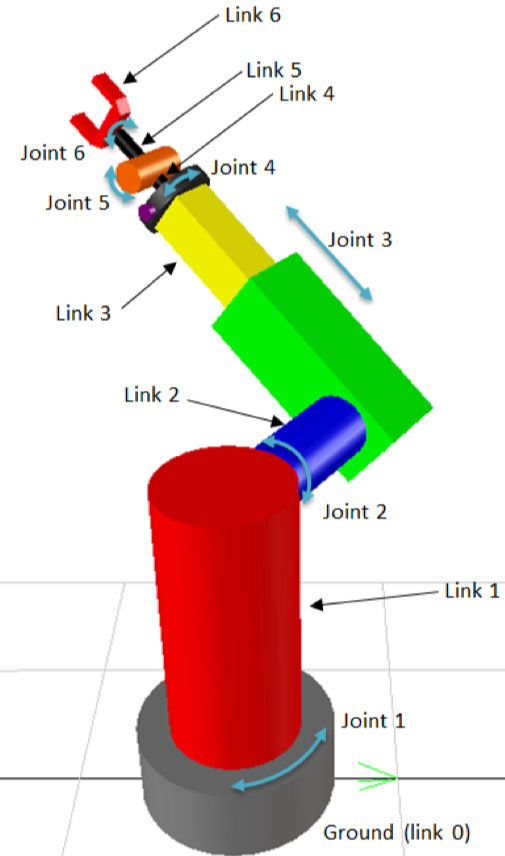

mdl_stanford
qc=[0 -pi/4 0.77 pi 0 0]
stanf.links(1, 5).a=0.2  
stanf.plot(qc, 'zoom',3)
stanf.teach

### Two vector representation

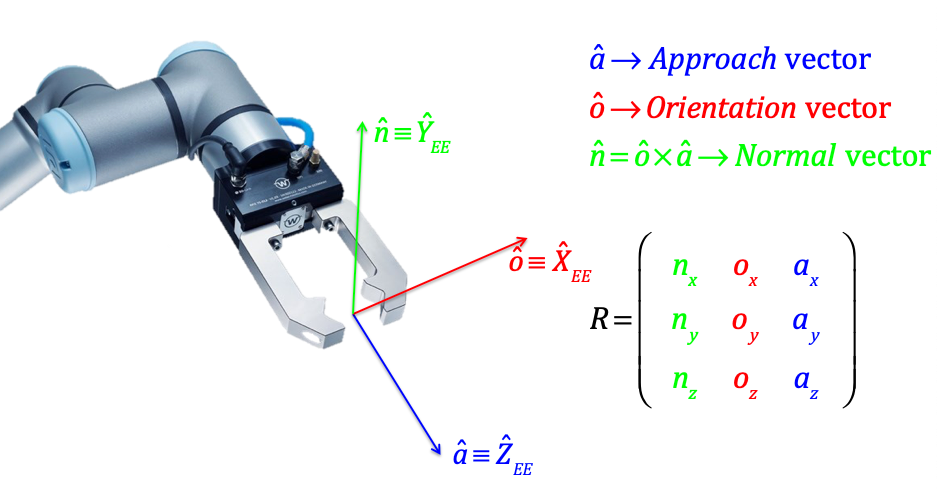

Play with q4, q5 and q6 to notice the effect. Think in $\hat Z_{EE}$ components

mdl_puma560
p560.plot(qz,'zoom',1.5)
p560.teach('approach')

It is useful whe you know direction and orientation of the tool

A=[0 0 1]' % Unitary vector of the known direction
O=[0 1 0]' % Unitary vector of the known direction
R = oa2r(O, A) % The reference Frame of the End Effector 
N=cross(O,A) % 'oa2r' function build the {EE} Refence Frame.

## Three angles, inverse problem

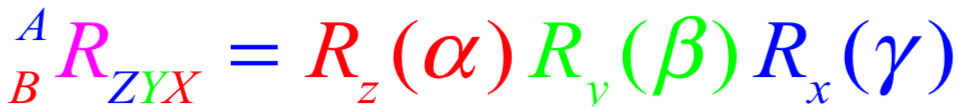

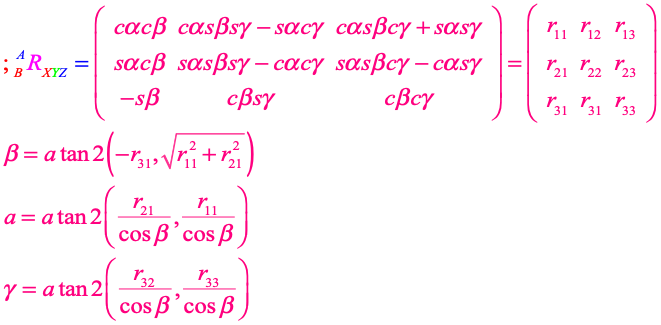

### By hand

Given a Rotation matrix extract the roll, pitch, yaw angles

zyx=[0.1 0.2 0.3] % [rotz roty rotx] i.e. [a b g]
R=rotz(zyx(1))*roty(zyx(2))*rotx(zyx(3))

beta=atan2(-R(3,1),sqrt(R(1,1)^2+R(2,1)^2))
alpha=atan2(R(2,1)/cos(beta),R(1,1)/cos(beta))
gamma=atan2(R(3,2)/cos(beta),R(3,3)/cos(beta))

### Using RTB

R=rpy2tr([0.3 0.2 0.1]) % Be carefully [g b a] but it makes rotzrotyrotx
rpy = tr2rpy(R, 'zyx') % Visit help tr2rpy. First roll, pitch and yaw

### The singularity $\beta =\pm \frac{\pi }{2}$

R=rpy2tr([0.3 pi/2 0.1]) % [g b a] 


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCaebbnrfifHhDYfgasaacH8sr
% ps0lbbf9q8WrFfeuY-ribbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-
% yr0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dc9Gqpi0d
% meaabaqaciGacaGaaeqabaWaaeaaeaaakabaaaaaaaaapeqaa8aaca
% WGsbWaaSbaaSqaaiaadQhacaWG5bGaamiEaaqabaGcpeGaeyypa0Za
% aeWaa8aabaqbaeqabmWaaaqaa8qacaaIWaaapaqaa8qacqGHsislca
% qGZbWaaeWaa8aabaWdbiabeg7aHjabgkHiTiabeo7aNbGaayjkaiaa
% wMcaaaWdaeaapeGaae4yamaabmaapaqaa8qacqaHXoqycqGHsislcq
% aHZoWzaiaawIcacaGLPaaaa8aabaWdbiaaicdaa8aabaWdbiaaboga
% daqadaWdaeaapeGaeqySdeMaeyOeI0Iaeq4SdCgacaGLOaGaayzkaa
% aapaqaa8qacaqGZbWaaeWaa8aabaWdbiabeg7aHjabgkHiTiabeo7a
% NbGaayjkaiaawMcaaaWdaeaapeGaeyOeI0IaaGymaaWdaeaapeGaaG
% imaaWdaeaapeGaaGimaaaaaiaawIcacaGLPaaaaaa!5A23!
\[{R_{zyx}} = \left( {\begin{array}{*{20}{c}}
  0&{ - {\text{s}}\left( {\alpha  - \gamma } \right)}&{{\text{c}}\left( {\alpha  - \gamma } \right)} \\ 
  0&{{\text{c}}\left( {\alpha  - \gamma } \right)}&{{\text{s}}\left( {\alpha  - \gamma } \right)} \\ 
  { - 1}&0&0 
\end{array}} \right)\]$$


rpy = tr2rpy(R) % Visit help tr2rpy

Play with Aircraft to enter in the singularity

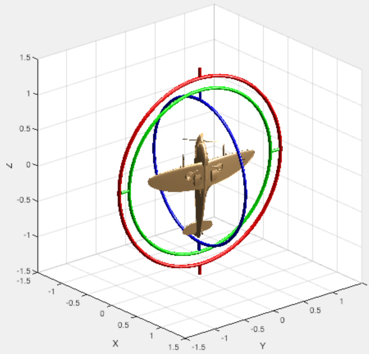

tripleangle

## Rotating about and arbitrary axis 

### More about (pre/post) multiplication

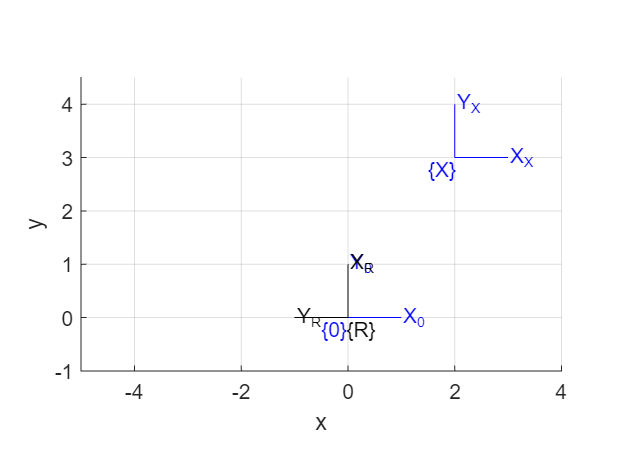

clf
plotvol([-5 4 -1 4.5]);
T0 = eye(3,3);
trplot2(T0, 'frame', '0');
hold on
X = transl2(2, 3);
trplot2(X, 'frame', 'X');
R = trot2(pi/2); % Operator
trplot2(R, 'frame', 'R','color','black');

Pay attention to both interpretations: Premutiplication / postmultiplication

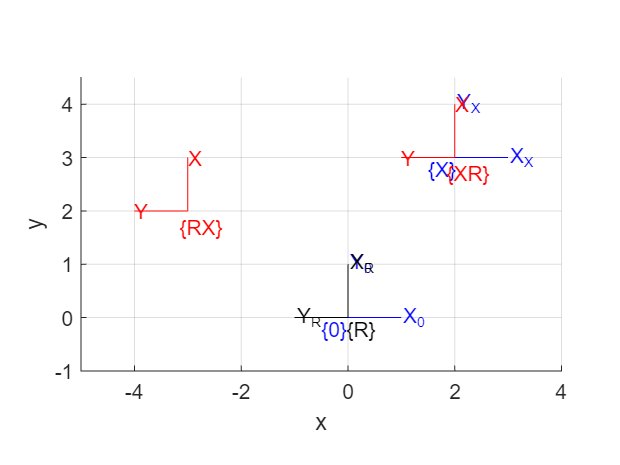

trplot2(R*X, 'framelabel', 'RX', 'color', 'r'); 
trplot2(X*R, 'framelabel', 'XR', 'color', 'r');

### 2D. Rotating about a point

C = [1 2]';
plot_point(C, 'label', ' C', 'textcolor', 'k', 'solid', 'ko')% RTB

RC = transl2(C) * R * transl2(-C)

RC =     0.0000   -1.0000    3.0000
    1.0000    0.0000    1.0000
         0         0    1.0000


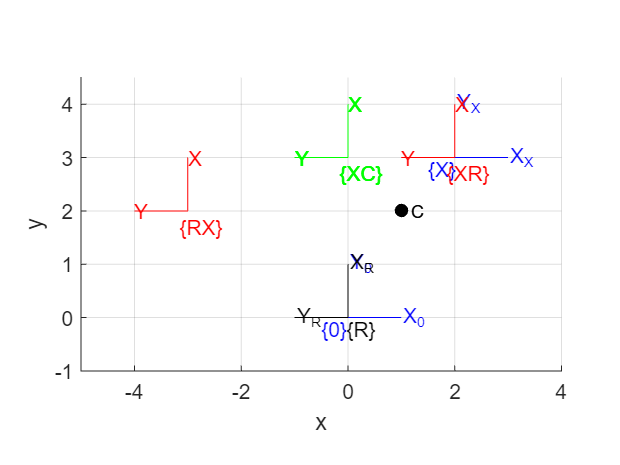

trplot2(RC*X, 'framelabel', 'XC', 'color', 'g');

### 3D. Rotating about a vector by hand

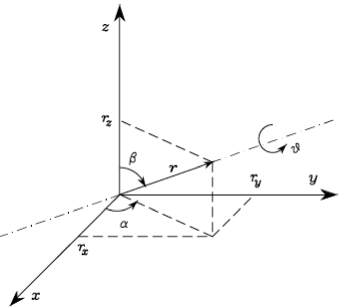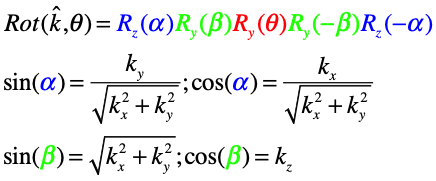

Given a unitary vector

v=[1 1 1]

v =      1     1     1


v=v/norm(v)

v =     0.5774    0.5774    0.5774


norm(v)

ans = 1.0000

The 'arrow' option requires https://www.mathworks.com/matlabcentral/fileexchange/14056-arrow3

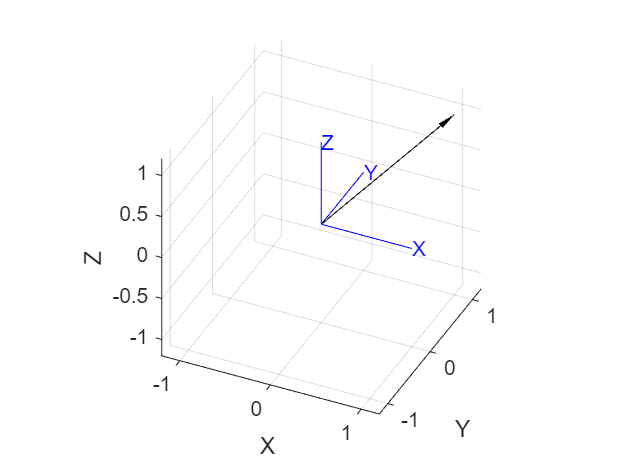

clf
trplot(eye(4),'color','b')
view(25,35)
hold on
arrow3([0 0 0],[1 1 1]) % to draw arrow

sin_alpha=v(2)/sqrt(v(1)^2+v(2)^2)

sin_alpha = 0.7071

cos_alpha=v(1)/sqrt(v(1)^2+v(2)^2)

cos_alpha = 0.7071

alpha=atan2(sin_alpha,cos_alpha)

alpha = 0.7854

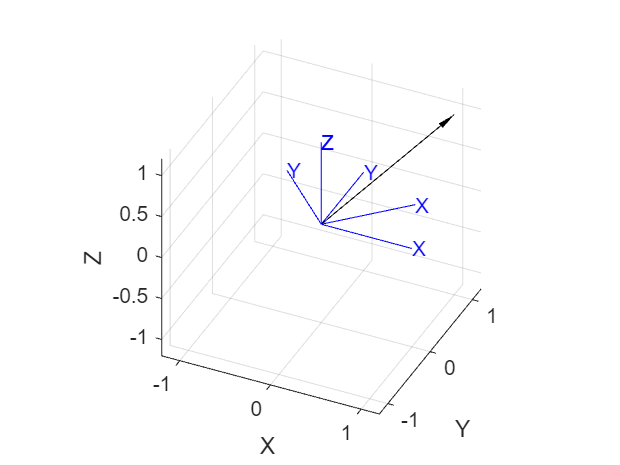

tranimate(rotz(alpha))

sin_beta=sqrt(v(1)^2+v(2)^2)

sin_beta = 0.8165

cos_beta=v(3)

cos_beta = 0.5774

beta=atan2(sin_beta,cos_beta)

beta = 0.9553

C=rotz(alpha)*roty(beta)% C bring Za  axis same as the vector K_hat 

C =     0.4082   -0.7071    0.5774
    0.4082    0.7071    0.5774
   -0.8165         0    0.5774


tranimate(rotz(alpha),C,40) 

### Cheking $\textrm{Av}=v$

The vector v does not change

theta=pi/6 % for example

theta = 0.5236

trot_k_theta=r2t(C)*trotz(theta)*(r2t(inv(C)))

trot_k_theta =     0.9107   -0.2440    0.3333         0
    0.3333    0.9107   -0.2440         0
   -0.2440    0.3333    0.9107         0
         0         0         0    1.0000


v_n=trot_k_theta*[v 1]'

v_n =     0.5774
    0.5774
    0.5774
    1.0000


### 3D. Rotating about a vector using RTB

See: Rotating_about_axis.mlx

Operator=angvec2tr(2*pi/3, [1 1 1])
New_p=Operator*[0 0.5 0 1]'

## Recovering ang/vector from a Rotating Matrix


$$C = \left( {\begin{array}{*{20}{c}}
  {{n_x}}&{{o_x}}&{{a_x}}&0 \\ 
  {{n_y}}&{{o_y}}&{{a_y}}&0 \\ 
  {{n_z}}&{{o_z}}&{{a_z}}&0 \\ 
  0&0&0&1 
\end{array}} \right);\;{\text{C = Matrix/Operator}}$$


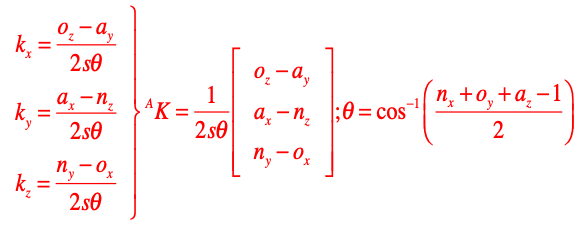

### From R to ang/vec by hand

CC=trot_k_theta
theta= acos((CC(1,1)+CC(2,2)+CC(3,3)-1)/2);
sin_theta=(sqrt((CC(3,2)-CC(2,3))^2+(CC(1,3)-CC(3,1))^2+(CC(2,1)-CC(1,2))^2))/2;
v_x=(CC(3,2)-CC(2,3))/(2*sin_theta);
v_y=(CC(1,3)-CC(3,1))/(2*sin_theta);
v_z=(CC(2,1)-CC(1,2))/(2*sin_theta);
v_the=[v_x v_y v_z]

### From R to ang/vec using RTB

[ang,vec]=tr2angvec(trot_k_theta)
pi/6